# Initialization

%rawdata = randi([0 1], [1 50e3]); 
%rawdata = [0];

rawdata = [1 0 1 1 0 1];
%rawdata = [1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1];

%fd      = 50;               % Data frequency
%fca     = 1.023e6;          % C/A code frequency
fd      = 5;               % Data frequency
fca     = 1.023e5;          % C/A code frequency
fc      = fca*20;        % Carrier frequency (Adjusted to not overload RAM)
%fc      = 1575.42e6;        % Carrier frequency
sv_id   = 1;                % Satellite Vehicle ID
n       = 1;                % BPSK(1) fc = n*1.023e6; %code rate BPSK(n) spreading code rate n*1.023 MHz
codeLength = round(1023/n);  
c_d = 20;

## Gold Code

shift_G1_reg = [ones(1,10)];
shift_G2_reg = [ones(1,10)];
SV = sv_id;
gc = gold_code(codeLength,shift_G1_reg,shift_G2_reg,SV);

## Data Modulation

d1  = upsampler(rawdata,length(gc)*c_d);                % Upsample data message
gc1 = expand(gc,length(rawdata)*c_d);                   % Extend gold code to the amount of data bits
data = (data_mapper(xor(d1,gc1)));    % Upsample to the frequency

fs = fc*10;                                         % sample frequency
mdata = upsampler(data,fs/fca);                      % Upsample data to the sampling frequency

t = 0:1/fs:length(rawdata)/fd-1/fs;                 % carrier timer
Carrier = exp(1i.*2*pi*fc.*t);                          % Carrier signal
msignal = mdata.*Carrier;                           % Modulated Signal

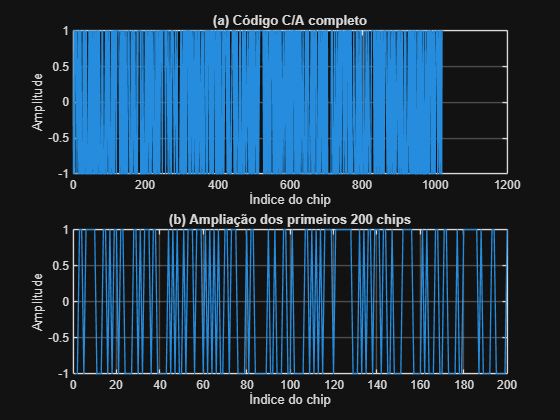

ca_code = data_mapper(gc);
figure('Name','Codigo CA');

subplot(2,1,1)
plot(ca_code,'LineWidth',1)
grid on
xlabel('Índice do chip')
ylabel('Amplitude')
title('(a) Código C/A completo')

subplot(2,1,2)
plot(1:200,ca_code(1:200),'LineWidth',1)
grid on
xlabel('Índice do chip')
ylabel('Amplitude')
title('(b) Ampliação dos primeiros 200 chips')

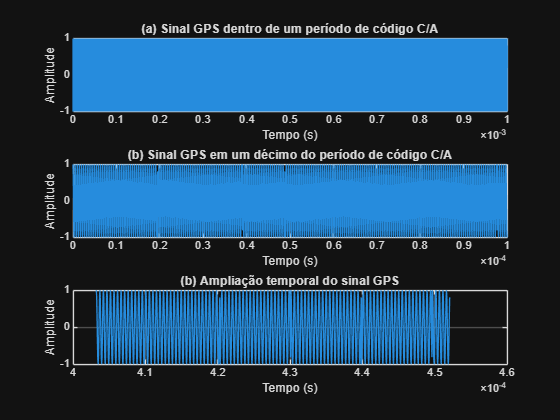

figure('Name','Sinal GPS');

idx = 1:length(msignal)/1200;   % ajuste conforme necessário
subplot(3,1,1)
plot(t(idx),real(msignal(idx)))
grid on
xlabel('Tempo (s)')
ylabel('Amplitude')
title('(a) Sinal GPS dentro de um período de código C/A')

%1 Período = lenght(msignal)/1200
idx = 1:length(msignal)/(1200*10);   % ajuste conforme necessário
subplot(3,1,2)
plot(t(idx),real(msignal(idx)))
grid on
xlabel('Tempo (s)')
ylabel('Amplitude')
title('(b) Sinal GPS em um décimo do período de código C/A')

subplot(3,1,3)
idx = 8250+(1:1000);   % ajuste conforme necessário

plot(t(idx),real(msignal(idx)))
grid on
xlabel('Tempo (s)')
ylabel('Amplitude')
title('(b) Ampliação temporal do sinal GPS')